# **HW2 - Extra problem 2: Euler Equations**

## Generate initial conditions

I1 = 3;
I2 = 2;
I3 = 1;

N = 100;
w_rand = randn(3,N);
w0 = zeros(3,N);
for i=1:N
    hg = w_rand(:,i).*[I1; I2; I3];
    hg_norm = hg/norm(hg);
    w = hg_norm./[I1; I2; I3];
    w0(:,i) = w_rand(:,i)/norm(w_rand(:,i));
end


## Generate and plot trajectories

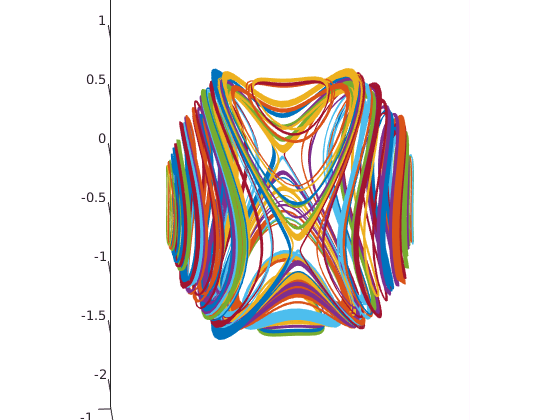

tspan = [0 10];

clf;
figure(1)
hold on
for i=1:N
    [t,y] = ode45(@euler_ode,tspan,w0(:,i));
    plot3(y(:,1), y(:,2), y(:,3));
end
axis equal 
axis vis3d
view(-160, 15)

## **Define ODE**

function [yout] = euler_ode(t, yin)
  I1 = 3;
  I2 = 2;
  I3 = 1;
  
  a = (I2 - I3)/I1;
  b = (I3 - I1)/I2;
  c = (I1 - I2)/I3;

  w1 = yin(1);
  w2 = yin(2);
  w3 = yin(3);
  w1dot = a*w2*w3;
  w2dot = b*w1*w3;
  w3dot = c*w1*w2;

  yout = [w1dot; w2dot; w3dot];

end